clear all

allResults = sensiAna_YJM(0.1,1);

allResults.maxT

ans = struct with fields:
     prop_R0: [3.2772 3.1344 3.0344]
    alpha_P0: [3.1152 3.1344 3.1507]
    alpha_P1: [2.5783 3.1344 3.2143]
    alpha_R0: [3.1209 3.1344 3.1480]
     omega_R: [3.1237 3.1344 3.1445]
     omega_P: [3.1456 3.1344 3.1247]
       Omega: [3.1325 3.1344 3.1361]
        Td_c: [3.1917 3.1344 3.0104]
         k_P: [3.1301 3.1344 3.1319]
         k_R: [3.1435 3.1344 3.1253]
         c_R: [3.1730 3.1344 3.0882]
         c_P: [3.0332 3.1344 3.0970]
       kappa: [3.4667 3.1344 2.6927]
       delta: [3.1005 3.1344 3.1216]
          s_: [3.1586 3.1344 3.1142]
       C_at0: [3.1322 3.1344 3.1364]
       C_oc0: [3.1398 3.1344 3.1296]
      C_veg0: [3.1184 3.1344 3.1514]
       C_so0: [3.1450 3.1344 3.1242]
         k_p: [3.0806 3.1344 3.1980]
         k_c: [3.1374 3.1344 3.1312]
         k_M: [3.1737 3.1344 3.0990]
         k_r: [3.1970 3.1344 3.0873]
         E_a: [3.0908 3.1344 3.1850]
        k_sr: [3.2215 3.1344 3.0776]
         k_t: [3.1174 3.1344 3.1567]
           c

res_ = allResults;
resNames = fieldnames(allResults.maxT);

give2barh = [];
fldnames  = fieldnames(res_.maxT);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxT.(fldname_)];
end

ctst = categorical(fldnames)'

ctst = 1×38 categorical array
     prop_R0      alpha_P0      alpha_P1      alpha_R0      omega_R      omega_P      Omega      Td_c      k_P      k_R      c_R      c_P      kappa      delta      s_      C_at0      C_oc0      C_veg0      C_so0      k_p      k_c      k_M      k_r      E_a      k_sr      k_t      c      A      S      tao_CH4      P_0      F_0      chi      zeta      f_max      omega      T_c      t_f 


% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
%sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
max_temp = max(give2barh, [],2);
min_temp = min(give2barh, [],2);
sizeBar = abs((max_temp)' - (give2barh(:,2))' + (give2barh(:,2))' - (min_temp)');
[A,sortIdx] = sort(sizeBar,'ascend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(resNames(sortIdx))';
%sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));
mn1 = mean(give2barh);
mn1 = mn1(2); 

resNames

resNames = 38×1 cell array
    {'prop_R0' }
    {'alpha_P0'}
    {'alpha_P1'}
    {'alpha_R0'}
    {'omega_R' }
    {'omega_P' }
    {'Omega'   }
    {'Td_c'    }
    {'k_P'     }
    {'k_R'     }
    {'c_R'     }
    {'c_P'     }
    {'kappa'   }
    {'delta'   }
    {'s_'      }
    {'C_at0'   }
    {'C_oc0'   }
    {'C_veg0'  }
    {'C_so0'   }
    {'k_p'     }
    {'k_c'     }
    {'k_M'     }
    {'k_r'     }
    {'E_a'     }
    {'k_sr'    }
    {'k_t'     }
    {'c'       }
    {'A'       }
    {'S'       }
    {'tao_CH4' }


resNames(7)

ans = 1×1 cell array
    {'Omega'}


resNames(15)

ans = 1×1 cell array
    {'s_'}


disp(apple)

Unrecognized function or variable 'apple'.

temp_str = resNames(1); % cell
if strcmp(temp_str{1}, 'prop_R0')
    resNames(1) = {'\rho_R'};
    resNames(2) = {'\alpha_{P0}'};
    resNames(3) = {'d'};
    resNames(4) = {'\alpha_{R0}'};
    resNames(5) = {'\omega_R'};
    resNames(6) = {'\omega_P'};
    resNames(7) = {'\Omega'};
    resNames(8) = {'d_c'};
    resNames(15)={'s'};
    temp_str2 = resNames(13);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1+2;
        resNames(13) ={'\kappa'};
    else
        incr = 0;
    end    
    
    resNames(11+incr) = {'\delta'};
    resNames(13+incr) = {'C_{at0}'};
    resNames(14+incr) = {'C_{oc0}'};
    resNames(15+incr) = {'C_{veg0}'};
    resNames(16+incr) = {'C_{so0}'};
    resNames(22+incr) = {'k_{sr}'};
    resNames(27+incr) = {'\tau_{CH4}'};
    resNames(30+incr) = {'\chi'};
    resNames(31+incr) = {'\zeta'};
    resNames(32+incr) = {'f_{max}'};
    resNames(33+incr) = {'\omega'};
end


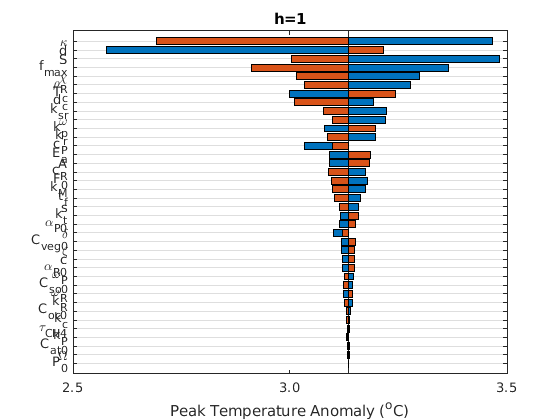

clf
barh(give2barh(sortIdx,1), 'stacked', 'BaseValue', mn1)
hold on
barh(give2barh(sortIdx,3),'stacked', 'BaseValue', mn1)
len__ = length(sortIdx);
yticks(1:len__)
set(gca, "YTickLabel", resNames(sortIdx))
title('h=1')
xlabel("Peak Temperature Anomaly (^oC)")
ax=gca;ax.YGrid='on';xtickformat('%,.1f')